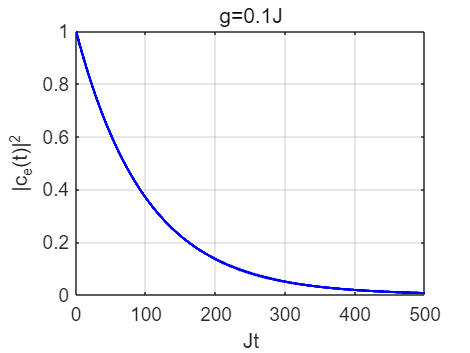

% Clear workspace, command window, and close all figures
clear;
clc;
close all;

% Parameters
N = 1000; % Example value, you can change it
delta = 0;
g = 0.1;
J = 1.0;
dt = 0.1; % Smaller time step for better accuracy
T = 500; % Total simulation time

% Initial conditions
c_e = 1.0; % Initial condition for c_e(t)
c_x = zeros(2*N+1, 1); % Initial condition for c_x(t) from -N to N

% Combine c_e and c_x into a single state vector
c = [c_e; c_x];

% Time vector
time = 0:dt:T;
num_steps = length(time);

% Initialize matrix to store the solution at each time step
C = zeros(2*N+2, num_steps);
C(:, 1) = c;



% Runge-Kutta 4th order method iteration
for n = 1:num_steps-1
    k1 = dt * derivatives(C(:, n), N, delta, g, J);
    k2 = dt * derivatives(C(:, n) + 0.5 * k1, N, delta, g, J);
    k3 = dt * derivatives(C(:, n) + 0.5 * k2, N, delta, g, J);
    k4 = dt * derivatives(C(:, n) + k3, N, delta, g, J);
    C(:, n+1) = C(:, n) + (k1 + 2*k2 + 2*k3 + k4) / 6;
end

% Extract solutions
c_e_sol = C(1, :);
c_x_sol = C(2:end, :);

% Plot |c_e(t)|^2 vs time
figure;
plot(time, abs(c_e_sol).^2, 'b', 'LineWidth', 1.5);
xlabel('Jt');
ylabel('|c_{e}(t)|^2');
title('g=0.1J');
grid on;

% save as PDF
print('g=0.1J_ce.pdf', '-dpdf');

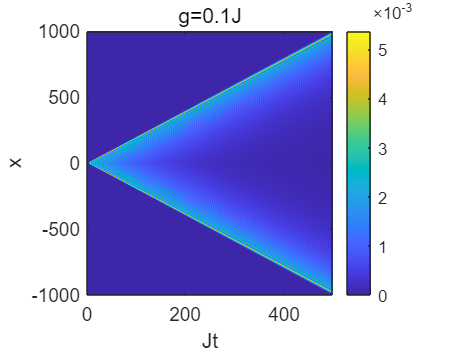



% Plot |c_x(t)|^2 as a heatmap
figure;
imagesc(time, -N:N, abs(c_x_sol).^2);
colorbar;
xlabel('Jt');
ylabel('x');
title('g=0.1J');
set(gca, 'YDir', 'normal'); % Ensure y-axis is correctly oriented
% save as PDF
print('g=0.1J_cx.pdf', '-dpdf');


% % Extract and plot |c_0(t)|^2 vs time
% c_0_sol = c_x_sol(N+1, :); % c_0 corresponds to the middle element in c_x_sol
% figure;
% plot(time, abs(c_0_sol).^2, 'r', 'LineWidth', 1.5);
% xlabel('Jt');
% ylabel('|c_{0}(t)|^2');
% title('|c_{0}(t)|^2 vs Time');
% grid on;
% % Define function for the derivative

function dc = derivatives(c, N, delta, g, J)
    c_e = c(1);
    c_x = c(2:end);
    
    dot_c_e = -1i * delta * c_e - 1i * g * c_x(N+1); % Note: c_0 is at index N+1
    dot_c_x = zeros(2*N+1, 1);
    for x = -N:N
        index = x + N + 1;
        if x == -N
            dot_c_x(index) = -1i * J * c_x(index+1) - 1i * g * (x == 0) * c_e;
        elseif x == N
            dot_c_x(index) = -1i * J * c_x(index-1) - 1i * g * (x == 0) * c_e;
        else
            dot_c_x(index) = -1i * J * (c_x(index+1) + c_x(index-1)) - 1i * g * (x == 0) * c_e;
        end
    end
    
    dc = [dot_c_e; dot_c_x];
end